TrendTradingMainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat IndexTT PriceTTFullRaw VolumeTTFullRaw
IndexTT ;
PriceTTFullRaw ;
VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

PriceTTFull = fillmissing (PriceTTFullRaw, "previous") ;
PriceTTFull = fillmissing (PriceTTFull, "next") ;

VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;


Split dataset into IST and OST

nRowFull = int64 (size (PriceTTFull,1)) ;
nRowISTproportion = 80/100 ;  % Proportion of dataset to be in Sample Dataset
nRowIST = int64(round(nRowISTproportion*nRowFull)) ;
nRowOST = round (nRowFull-nRowIST) ;

% IST dataset
PricesIST = (PriceTTFull (1:nRowIST, :)) ;
VolumesIST = (VolumesTTFull (1:nRowIST, :)) ;

% OST dataset
PricesOST = (PriceTTFull (nRowIST:end, :)) ;
VolumesOST = (VolumesTTFull (nRowIST:end, :)) ;


Backtest

% Backtest input

x = [10^3 10^9 10 -10 20 10^6 20 30 25 5 40 -8 4]

x =        1000.00 1000000000.00         10.00        -10.00         20.00    1000000.00         20.00         30.00         25.00          5.00         40.00         -8.00          4.00


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn               8.55       
    SharpeRatio               0.08       
    Volatility                0.01       
    AverageTurnover           0.10       
    MaxTurnover               0.86       
    AverageReturn             0.00       
    MaxDrawdown               0.33       
    AverageBuyCost           57.83       
    AverageSellCost          77.03       


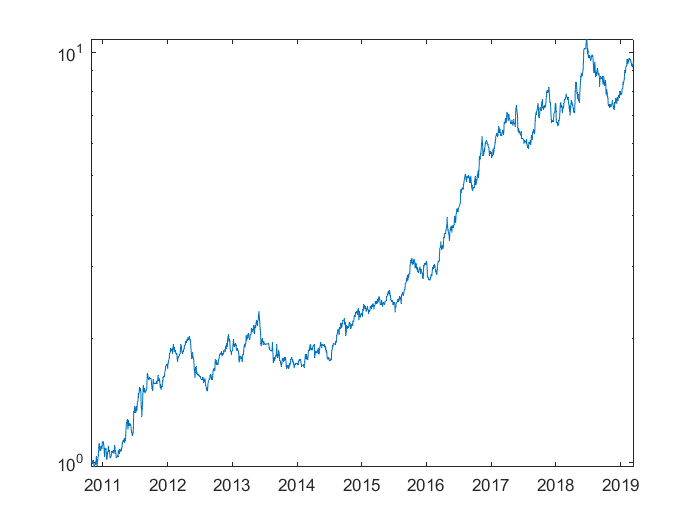

EndCumSum = 1×1 timetable
       Time        TrendTradeStrategy
    ___________    __________________

    18-Mar-2019           9.55       


TradingPeriod =           8.40


CAGR =           0.31


SharpeRatio =          -1.26


Sortino =          -1.86


MaxDD =           0.33


StartEndMaxDD = 2×1 datetime array
   22-Jun-2018
   26-Nov-2018


Elapsed time is 20.471501 seconds.


SharpeRatio =          -1.26



% LowSkipValTreshCorrection = x(1) ; 
% MinValue = x(2) ;
% MomContDays = x(3) ; 
% MomContRetTrheshold = x(4) ; 
% LowLiquidDays = x(5) ;
% LowLiquidThreshold = x(6) ;
% LiquidSurgThreshold = x(7) ;
% MomMainDays = x(8) ;
% MomMainRetThreshold = x(9) ;
% PostSignalBufferDays = x(10) ;
% StopLossLookbackWindSz = x(11) ;
% StopLossThreshold = x(12) ;
% RebalanceFreq = x(13) ;

% Call the function
SharpeRatio = TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) 

Optimize parameters in IST

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', ...
    false, "FunctionTolerance", 0.05, "MaxGenerations",20, 'MaxTime', 60*5)

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    MaxStallTime: Inf
                     MutationFcn: {@mutationgaus

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping})

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    


FitnessFunction = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% ConstraintFunction = @nlconGA ;
IntCon = 1:nvars ;

[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [],IntCon, options)


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSum =

  timetable

       Time        TrendTradeStrategy
    ___________    __________________

    18-Mar-2019            1         


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

   NaN


Sortino =

   NaN


MaxDD =

     0



Error using matlab.internal.datatypes.parenReference_1D (line 12)
Array indices must be positive integers or logical values.

Error in datetime/parenReference (line 19)
        obj.dat

Apply the parameters into OST

Examine OST

Closing

toc

Elapsed time is 322.128148 seconds.
